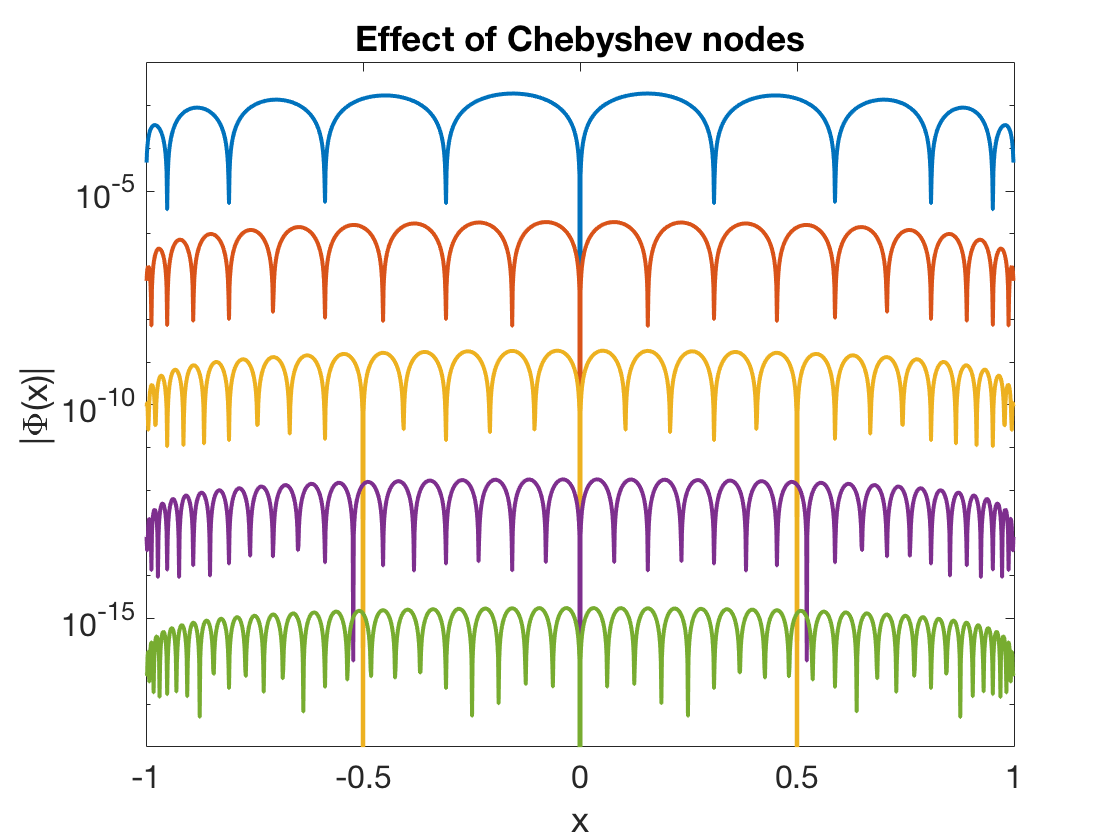

x = linspace(-1,1,1601)';
Phi = zeros(size(x));
for n = 10:10:50
    theta = linspace(0,pi,n+1)';
    t = -cos(theta);                    
    for k = 1:length(x)
        Phi(k) = prod(x(k)-t);
    end
    semilogy(x,abs(Phi))
    hold on
end
axis tight, title('Effect of Chebyshev nodes')    % ignore this line
xlabel('x'), ylabel('|\Phi(x)|')   % ignore this line
ylim([1e-18 1e-2])   % ignore this line

The convergence is a bit slower in the middle than with equally spaced points, but far more uniform over the entire interval, which is the key to global convergence. 